# ECSE 343: Numerical Methods for Engineers- Assignment 1- part a

Due Date:  21st Feb. 2023

Student Name: Chenyi Xu

Student ID:    260948311

## Please type your answers and write you code in this .mlx script. If you choose to provide the handwritten answers, please scan your answers and include those in SINGLE pdf file.

## Please submit this **.mlx** file along with the **PDF** copy of this file.

## **Question 1:  Fixed Point Number Repersentation (10 marks)**

One possible way to store represent numbers in computer is to use **fixed **point integer method. Suppose we have a 64-bit fixed point integer representation, where we use 31bits for the integer part and 32 bits for the fraction part and 1 bit is reserved for the the sign bit. The visual representation of our number is shown below, 

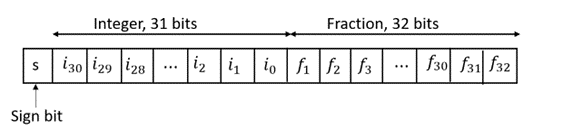

Using the above scheme any number can be represented as following


$$i_{30} 2^{30} +\ i_{29} 2^{29} +\ldots+\ i_1 2^1 +i_2 2^0 +f_1 2^{-1} +f_2 2^{-2} +\ldots+f_{31} 2^{-31} +f_{32} 2^{-32}$$


For example, 43.625  can be represented as,

Where, 0 is used to represent the positive sign and  0000...0000101011 is a 31 bit binary value for decimal 43 and 1010000...0000 is a 32 bit binary value for fractional 0.625.

    a) Find the smallest and the largest positive number that can be represented in this format.

  *% type your answer here*

***largest:***

*s bit = 0*

*Integer 1111....1111(31 bits)*

*Fraction 111....1111(32 bits)*

***smallest:***

*s bit = 0*

*Integer 000...000(31 bits)*

*Fraction 000.....0001(32 bits)*

    b) Give an upper bound on the *absolute *error due to rounding on numbers stored using the above **64-bit fixed point** representation.

*    % type your answer here*

## 0.5

    c) Give an upper bound on the *relative *error due to rounding on numbers stored using the above **64-bit fixed point** representation.

    *% type your answer here*

##   2^(-32)

    d) Find the largest and smallest positive numbers that can be represented as a **64-bit****floating** **point **number? 

        ***% type your answer here***

* 11 bits exponent, 52 bits mantissa*

*    Bias = 2^(11-1) - 1 = 1023*

**largest:**

sign bit = 0;

mantissa: 111...11111(52 bits)

E = 111...1110 (11 bits)

e = 2046 - 1023 = 1023

Therefore, the largest positive number can be represented as 1.11111...1111(52 bits) x 2^(1023)

= 1.78769 x10^308

**Smallest: **

sign bit = 0

E = 0000....001(11 bits)

e = 1 - 1023 = -1022

Therefore, the smallest positive number can be represented as 1.0000..000(52 bits) x 10^(-1022) = 2.22507 x 10^(-308)

## Question 2:  Round off errors **(10 marks)**

    a)  The MATLAB function `eps(x) `provides difference between x and the next higher number that can be stored using floating point representation on a computer. 

 Use the MATLAB function `eps`(x) to compute the value of $ $\epsilon $$  for different values of n. Use x = 1,2,3,4,5,…,1000.  Plot $ $\epsilon $$  vs *x *, explain the results obtained.

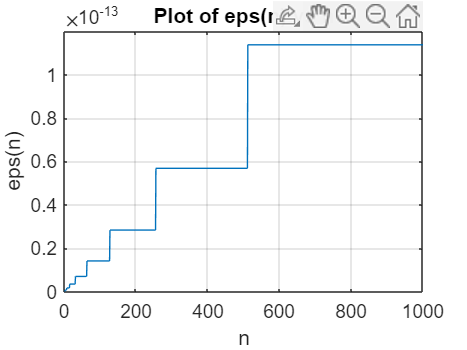

% write your code here 
n = 1:1:1000;

figure;
plot(n, eps(n));
grid on;
xlabel('n');
ylabel('eps(n)');
title('Plot of eps(n) vs n');

 The function is used to computer the distance between the number and the next higher number that can be represented. The difference is 2^a(where a is the smallest bits of mantissa) times value of exponent. The gap between adjacent floating point increases as the number become larger. Therefore, the graph generated looks like a staircase.  

  b) Write your own function named *myeps(x)* to compute difference between x and the next higher number. Your function should take integer x as input and provide the  difference between x and the next higher number that can be stored in 64 bit floting point  reprsentation. Write your function in the appendix of this mlx file and test it in the cell below.

Test your function for  x = 1,2,3,4,5,…,1000. Plot the output of your function vs x, explain the results obtained.

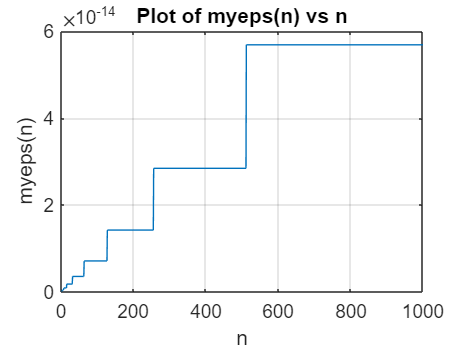

% write your code here 
n = 1:1:1000;

figure;
plot(n, arrayfun(@myeps, n));
grid on;
xlabel('n');
ylabel('myeps(n)');
title('Plot of myeps(n) vs n');

*% type your answer here*

`  The graph appears to have the same pattern with the graph in part A. As the magnitube of number increases, the gap between adjacent number increases. Therefore, a staircase like graph is generated. A while loop is used in the code, The function intialize the output variable out to 1. Then it enter the loop as long as x + out > x. This expression checks whether adding the out would result in a number bigger than x which would indicate out would be the gap between neighbout number. Each iteration out is divided by 2. `

` c) `The relative error due to rounding is defined as,

                                                            
$$\eta_x = \left| \frac{x - \hat{x}} {x} \right |$$


    where x is the actual value and $\hat{x}$ is the value stored as a  floating point number. Write a function to estimate the value of the relative error as a  function of the stored value, you may use the MATLAB function provided in part (a). 

Use $\hat{x}$ = 1,2,3,4,5,…,1000.  Plot $\eta_x$vs $\hat{x}$, explain the results obtained using your function.  Is there an upper bound for it?  If so what is it? 

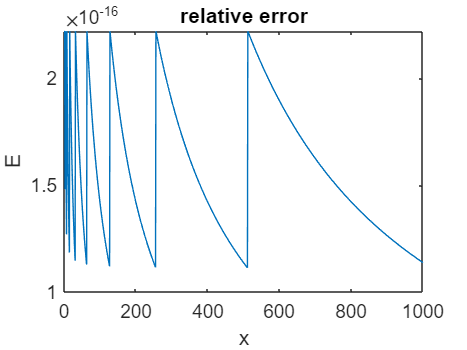

% write your code here
x = 1:1:1000;
E = eps(x) ./x;

figure;
grid on;
plot(x, E)
title('relative error')
xlabel('x')
ylabel('E') 

*% type your answer here*

*Within the same order of magnitube, the relative error decreases as x increases as spacing between adjacent floadtinf poinr number is smaller for laeegr values of x within same order. Spikes as shown in the graph happpens when x crosses over to the next higher magnitube. *

*yes, there is an upbound for this. 2.2 x (10^-16) based on the graph.*

*It can be derived numerically using 2^-52. The limit is determined by the bits of mantissa of the floating point. For a 64 bits number, the upper bound is 2^-52 which equals to 2.2 x (10^-16)*

d) The MATALB function call `eps(‘single’)` computes the machine epsilon for single precision (32bit) floating point numbers.

  Using your knowledge of the floating-point representation find an expression that computes the output of that funciton.

*% type your answer here*

output = 2^(-23)

## Question 3:  Numerical Derivatives **(10 marks)**

The derivative of a function, f(x), can be computed using the finite difference method, which can be derived using the first-order terms of the Taylor series expansion of the function, about : 

$f{\left(x_0 +h\right)}=f{\left(x_0 \right)}+hf^{\prime } {\left(x_0 \right)}+\frac{1}{2!}f^{\prime \prime } {\left(x_0 \right)}h^2 +\frac{1}{3!}f^{\prime \prime \prime } {\left(x_0 \right)}h^3 +\ldots$                    (2.1)

Rearranging terms to solve for $f^{\prime } {\left(x_0 \right)}$  and ignoring (truncating) the higher-order terms, we obtain the first order approximation of derivative

$f^{\prime } {\left(x_0 \right)}\;\approx \frac{f{\left(x_0 +h\right)}-f{\left(x_0 \right)}}{h}$                              (2.2)

    In this part, we will implement the code to compute the derivative of tan(x) at $x_{0\;} =\frac{\pi }{4}$ using the divided differences formula shown in equation (2.2).  

    a) Assuming that $h << 1$, find an expression for an estimate of the truncation error in eq. (2.2)?

        *% type your answer here*


$$f{\left(x_0 +h\right)}=f{\left(x_0 \right)}+hf^{\prime } {\left(x_0 \right)}+\frac{1}{2!}f^{\prime \prime } {\left(x_0 \right)}h^2 +\frac{1}{3!}f^{\prime \prime \prime } {\left(x_0 \right)}h^3 +\ldots$$
  

   $hf^{\prime } {\left(x_0 \right)}$ = $f{\left(x_0 +h\right)}$-$f{\left(x_0 \right)}$-$\frac{1}{2!}f^{\prime \prime } {\left(x_0 \right)}h^2$-$\frac{1}{3!}f^{\prime \prime \prime } {\left(x_0 \right)}h^3$-...

$f^{\prime } {\left(x_0 \right)}$ =  $\frac{f\left(x_0 +h\right)-f\left(x_0 \right)}{h}$ - $\frac{1}{2!}f^{\prime \prime } {\left(x_0 \right)}h$- $\frac{1}{3!}f^{\prime \prime \prime } {\left(x_0 \right)}h^2$

Therefore, the Truncation error $=\frac{hf^" \left(x\right)}{2!}$

    b) Use the cell below to implement the numerical derivative of  tan(x) using (2.2). Compute the numerical derivative $f'(x_0)$   for 100 logarthimically spaced values of *h *between ${10}^{-20\;}$ to ${10}^0$.  Also, evaluate the expression for truncation error obtained in part a) for different values of h. 

Compute the absolute error  between the analytical value of derivative and the estimated value of the derivative obtained using equation (2.2).

Plot the absolute error and the truncation error vs h on the same plot.  Explain the behavior of error as function of h as shown on the plot.

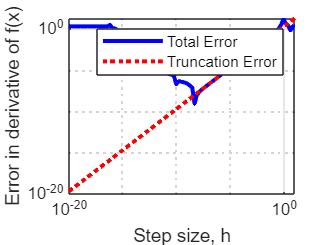

h = logspace(-20,1,100);  % logarithmically spaced values of h
x0 = pi/4; % value of x for which the derivative is to be computed
f = tan(x0); % value of the function at x
df = 1/(cos(x0)^2); % first derivative 
df_2 = 2*(sin(x0)/(cos(x0)^3)); % second derivative 

total_absErr = zeros(1,100);
truncation_error = zeros(1,100);

for i = 1:100
   
    f_p(i) = (tan(x0 +h(i)) - f)/h(i); % numerical derivative using (2.2)

    total_absErr(i) = abs(df - f_p(i)); % absolute error

    truncation_error(i) = (h(i)/2)*df_2; % truncation error
end

clf
figure(1)
loglog(h,total_absErr,'b','linewidth',2,'displayname','Total Error')
hold on
loglog(h,truncation_error,'r:','linewidth',2,'displayname','Truncation Error')
xlabel('Step size, h')
ylabel('Error in derivative of f(x)')
grid on
legend

        ***% type your answer here***

As h decreases, both total absolute error and truncation error decreases. At a certain point, the truncation error would continur decreases but the total absolute error would start to increase. 

As h approaches zero, truncation error is more accurate than total error. The terms we ignored in Taylor's series become more significant here. However, as the step size increases, total error and truncation error eventually starst to overlap. 

   **  c) In  part (b), at which value of h did you obtain the minimum error. Justify your answer and show all the computations.**

***% type your answer here ***

*4.64e-9 the minimum error is obtained based on the graph obtained in b. *

*Total error = rounding error + truncation error *

* = *$\frac{hf^" \left(x_0 \right)}{2!}$+ $\frac{e_1 \;*f\left(x+h\right)-e_2 *f\left(x\right)}{h}$

Derivative relative to h

0 = $\frac{f^" \left(x_0 \right)}{2!}$ - $\frac{e_1 \;*f\left(x+h\right)-e_2 *f\left(x\right)}{h^2 }$


$$h^2 =\frac{2e\left(f\left(x+h\right)-f\left(x\right)\;\right)}{f^" \left(x_0 \right)}$$


h = sqrt($\frac{2e\left(f\left(x+h\right)-f\left(x\right)\;\right)}{f^" \left(x_0 \right)}$)


$$h\approx \textrm{sqrt}\left(2e\right)\approx \textrm{sqrt}\left(2*2\ldotp 2*{10}^{-16} \right)=2\ldotp 09\;\times \;{10}^{-8}$$


d**) Another way to compute the derivative is to use the***** Central Difference method*****.    Writing the Taylor series expansion of **$f\left(x_0 -h\right)$** around **$x_0$**, we get **

f$\left.{\left(x_0 -h\right)}=f{\left(x_0 \right)}+f^{\prime } {\left(x_0 \right)}\ \left(-h\right)+\frac{1}{2!}f^{\prime \prime } {\left(x_0 \right)}h^2 +\frac{1}{3!}f^{\prime \prime \prime } {\left(x_0 \right)}{\left(-h\right.}^3 \right)+\ldots$          (2.3)

Subtracting (2.3) from (2.1),  and ignoring the higher-order terms, we get

$f^{\prime } {\left(x_0 \right)}\approx \frac{f{\left(x_0 +h\right)}-f{\left(x_0 -h\right)}}{2h}-\frac{1}{3!}f^{\prime \prime \prime } {\left(x_0 \right)}{\ h}^2 -\frac{1}{4!}f^{\prime \prime \prime \prime } {\left(x_0 \right)}{\ h}^3 +\ldots$           (2.4)

Truncating the higher order terms, we get the expression for *Central Difference *approximation for the derivative as, 

$f^{\prime } {\left(x_0 \right)}\approx \frac{f{\left(x_0 +h\right)}-f{\left(x_0 -h\right)}}{2h}$                              (2.5)

What is the expression for truncation error? 

Use the cell below to compute the derivative of tan(x) at $x_0 =\frac{\pi }{4}$using the divided  differences formula shown in equation (2.5). You may use the code provided for part b) as a starting point. 

Include plot of  the absolute error and the truncation error vs h in your report.  

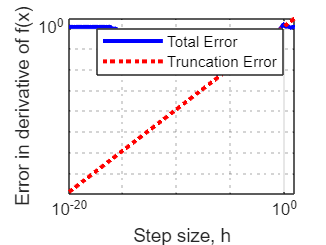

% write your code here
x0 = pi/4; % value of x for which the derivative is to be computed
f = tan(x0); % value of the function at x
df = 1/(cos(x0)^2); % first derivative 
df_2 = 2*(sin(x0)/(cos(x0)^3)); % second derivative 
df_3 = 4*((sec(x0)^2)*(tan(x0)^2)) + 2*((sec(x0)^4));

total_absErr = zeros(1,100);
truncation_error = zeros(1,100);

for i = 1:100
   
    f_p(i) = (tan(x0 +h(i)) - tan(x0-h(i)))/(2*h(i)); % numerical derivative using (2.4)

    total_absErr(i) = abs(df - f_p(i)); % absolute error

    truncation_error(i) = (1/6)*df_3*(h(i)^2); % truncation error
end





clf
figure(1)
loglog(h,total_absErr,'b','linewidth',2,'displayname','Total Error')
hold on
loglog(h,truncation_error,'r:','linewidth',2,'displayname','Truncation Error')
xlabel('Step size, h')
ylabel('Error in derivative of f(x)')
grid on
legend

*% type your answer here*

**Truncation error = **$\frac{1}{3!}f^{\prime \prime \prime } {\left(x_0 \right)}{\ h}^2$

e) Similar to part c). find the optimal value of  h where you obtain the minimum error. Justify your answer and show all the work.

*% type your answer here*

Based on the graph derived, the optimal value h where the min error achieved is 6.13e-07. 

*Total error = rounding error + truncation error *

*0 = *$\frac{e_1 f{\left(x_0 +h\right)}-e_2 f{\left(x_0 -h\right)}}{2h}$ +  $\frac{1}{3!}f^{\prime \prime \prime } {\left(x_0 \right)}{\ h}^2$

0 = $\frac{1}{6}\left(2h\right)$$f^{\prime \prime \prime } {\left(x_0 \right)}$ - $\frac{e\left(f{\left(x_0 +h\right)}-f{\left(x_0 -h\right)}\right)}{2\left(h^2 \right)}$

h = $\textrm{cubic}\;\textrm{root}\;\left(\frac{e\left(f{\left(x_0 +h\right)}-f{\left(x_0 -h\right)}\right)}{f^{\prime \prime \prime } {\left(x_0 \right)}*\left(\frac{2}{3}\right)}\right)=\textrm{cubic}\;\textrm{root}\left(\frac{\left(2\ldotp 2*{10}^{-16} \right)}{\frac{2}{3}}\right)=6\ldotp 9\times {10}^{-6}$

f) Which difference formula gives a smaller absolute error?  Explain.

*% type your answer here*

The central difference method gives a smaller absolute error. It has a higher order of accuracy. It uses a truncation error of O(h^2) while the other method has a truncation error of O(h). Moreover, the central difference method approximated derivative using the difference of points at either side of the point

## Question 4: Solving systems of equations. **(20 marks)**

    a) Write a function named *LU_decomposition.m * in the Appendix of this file to compute the** LU factorization using Gaussian Elimination. **

    b) Write a function named ***LU_rowpivot****.m *to compute the Gaussian Elimination based LU factorization **using the partial pivoting** (row pivoting,). Choose the elements with maximum magnitude as pivots. The function should take matrix  as the input and should output L, U and P matrices. Write your function in the Appendix of this file.

    c)  Write the  functions named ***forward_sub****.m *and ***backward_sub****.m*  to compute the forward and backward substitutions, respectively. Add  your functions in the appendix of this file.

    d)  In the cell below use the LU decomposition implemented in part (a) along with forward and backward substitution functions written in part (c) to solve the following system of equations. List the values of vector X obtained.  


$$\underset{A}{\underbrace{{\left[\begin{array}{cccc}
1e-16 & 50 & 5 & 9\\
0.2 & 5 & 7.4 & 5\\
0.5 & 4 & 8.5 & 32\\
0.89 & 8 & 11 & 92
\end{array}\right]}} } \underset{X}{\underbrace{{\left[\begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right]}} } =\ \underset{b}{\underbrace{{\left[\begin{array}{c}
40\\
52\\
18\\
95
\end{array}\right]}} }$$


A = [1e-16, 50, 5, 9; 0.2, 5, 7.4, 5; 0.5, 4, 8.5, 32; 0.89, 8, 11, 92]; 
b = [40; 52; 18; 95]; 
x = zeros(4, 1); 
%A = LU
[L, U] = LU_decompositon(A)

L = 1.0e+15 *

    0.0000         0         0         0
    2.0000    0.0000         0         0
    5.0000    0.0000    0.0000         0
    8.9000    0.0000    0.0000    0.0000


U = 1.0e+17 *

    0.0000    0.0000    0.0000    0.0000
         0   -1.0000   -0.1000   -0.1800
         0         0   -0.0000    0.0000
         0         0         0    0.0000


%LUx = b
%Ly = b --> forward sub to find y
y = forward_sub(L, b);

%Ux = y -->backwad sub to find x
x = backward_sub(U, y)

x =  -426.3256
   -1.0469
   13.1250
    2.9688




residual_1 = A*x-b;

 x obtained [-426.3256; -1.0469; 13.1250; 2.9688]

   e) In the cell below use the LU decomposition with partial pivoting implemented in part (b) along with forward and backward substitution functions written in part (c) to solve the above system of equations. List the values of vector X obtained.  

A = [1e-16, 50, 5, 9; 0.2, 5, 7.4, 5; 0.5, 4, 8.5, 32; 0.89, 8, 11, 92]; 
b = [40; 52; 18; 95]; 
x = zeros(4, 1); 
[L, U, P] = LU_rowpivot(A);
%LUx = Pb, y= Ux --> forward sub
y = forward_sub(L, P*b);
%Ux = y -->backward sub
x = backward_sub(U, y)

x =  -595.4623
   -2.1518
   21.6035
    4.3971




residual_2 = A*x-b;


  x obtained [-595.4623; -2.1518; 21.6035; 4.3971]

  f) Comment on solutions obtained in part (d) and (e). Use the residual to determine which solution is more accurarte.

*        % type your answer here*

norm1 = norm(residual_1)

norm1 = 77.6246

norm2 = norm(residual_2)

norm2 = 8.5561e-14

*norm 1 is 77.6246. norm 2 is 8.5561e-14. The residual is calculated using the equation residual = A*x - b. The norm of two residues are then computed respectively. The residual obtained in part e is way smaller than the residual in part d. therefore, solution from part e is more accurate. *

## Appendix

Write your functions here.

## Write code for Question 2 here

function out= myeps(x)

%write your code here
%out = 2^(-52) * 2 .^(-log2(x));
%for
out = 1;
while (x + out) > x
    out = out/2;
end


end

## Write code for Question 3 here

function [L, U] = LU_decompositon(A)
% L is lower triangular matrix
% U is upper triangular matrix

[m, n] = size(A);
%  L --> identity matrix,  U --> A
L = eye(m);
U = A;

% iterate over columns
for j = 1:n-1
    % iterate over rows 
    for i = j+1:m
        L(i, j) = U(i, j)/U(j, j);     
        % Gaussian elimination
        U(i, j:n) = U(i, j:n) - L(i, j)*U(j, j:n);
    end
end

end



function [L, U, P] = LU_rowpivot(A)
% L  is lower triagular matrix
% U is upper triangular matrix 
% P is the permutation matrix
% P*A = L*U
% YOUR CODE GOES HERE

% initialization
[m, n] = size(A);
P = eye(n);
L = eye(n); 
U = A;

%outter loop column
for j = 1: n-1
    %largest abs value in the column
    [max_value, pivot]= max(abs(U(j:n, j)));
    %pivot 
    pivot = pivot + j -1; 
    %swap this row with current row 
    %swap P & U
    %syntax for swtch rows A([2, 3],:)=A([3, 2],:)
    %2 and 3
    U([j,pivot],j:n) = U([pivot,j],j:n);
    L([j,pivot],1:j-1) = L([pivot,j],1:j-1);
    P([j,pivot],:) = P([pivot,j],:);
    %LU operation
    %inner loop row 
    for i = j+1:n
        L(i,j) = U(i,j)/U(j,j);
        U(i,j:n) = U(i,j:n) - L(i,j)*U(j,j:n);
    end

end
end

function y = forward_sub(L,b)
% y is the vector
% L is the lower triangular matrix
%    YOUR CODE GOES HERE

% initialization
[m, n] = size(L);
y = zeros(m, 1); 

for i = 1 : m
    y(i) = (b(i)-(L(i,1:i-1)*(y(1:i-1))))/L(i, i);
end

end 

function X = backward_sub(U,y)
% X is the vector
% U is the upper triangular matrix
%    WRITE YOUR CODE HERE
[n, m] = size(U);
X = zeros(n, 1);

for i = n : -1 : 1 
    X(i) = (y(i) - U(i, i+1:n)*(X(i+1:n)))/U(i, i);
end
end 



